addpath('./functions');
addpath('./data');

load('bignet.mat')
load('ood_detection.mat')
[XTrain, YTrain, XTest, YTest] = load_data('data');

analyzeNetwork(bignet)

layer = "maxpool 2x2_5"

layer = "maxpool 2x2_5"

trainFeatures = activations(bignet, XTrain, layer, OutputAs="rows")

trainFeatures = 50000×512 single matrix
    1.2734    1.2053    1.2557    0.7447    1.2062    1.3451    1.3466    1.2777    1.2663    0.9504    0.8249    1.0635    1.5722    0.9464    1.5007    1.0787    1.2562    0.9988    1.0763    1.3718    1.2669    1.2654    1.7915    1.5222    1.5204    1.2177    1.3622    1.2807    0.9515    0.9679    0.8737    1.5876    1.1293    0.8103    1.1370    0.9598    1.3775    1.0814    0.9362    1.1652    1.0777    1.6139    1.2895    1.5781    1.1583    0.5392    0.5036    1.1696    1.1249    1.5696
    0.6204    1.4702    0.6766    0.6545    0.9122    1.4813    1.3359    1.0959    1.2408    1.6451    1.4264    1.4743    1.7689    0.8024    1.2569    1.3092    1.4961    1.2348    0.9640    1.0715    1.5814    1.4743    0.2496    1.4441    1.5185    1.5234    1.3843    0.8307    1.2388    1.2505    0.9821    1.2545    0.8933    0.9520    1.5939    1.4279    0.3418    0.3947    1.6302    1.1132    1.3214    1.0032    2.0591    0.5037    1.5480    1.346

testFeatures = activations(bignet, ood_detection.data, layer, OutputAs="rows")

testFeatures = 1000×512 single matrix
    0.9402    1.2467    1.2121    0.5531    1.0277    1.5947    0.8526    0.8322    1.2642    0.9306    1.1478    1.4921    1.0127    0.9519    1.3039    1.3465    1.5740    1.1296    1.0087    1.1902    1.1715    1.4502    1.0207    1.3370    1.4465    1.4229    0.9205    1.0849    1.2508    1.3149    1.1202    1.9331    0.8287    1.5264    1.3243    1.0832    0.7789    1.0888    1.2196    1.0913    1.1984    1.0476    1.6513    1.1994    1.4590    1.2411    1.1519    1.2788    1.3871    0.8843
    1.3835    1.5148    1.7515    0.8226    1.4177    1.2814    1.2403    1.1211    1.0663    2.2325    1.9099    1.6048    1.3918    1.2749    1.2240    1.5320    1.3842    1.7318    1.1086    1.0993    1.7334    1.9179    1.7117    1.3907    1.6367    1.5789    1.7638    0.7175    1.1998    1.3791    0.9141    1.3961    1.2568    2.0640    1.5504    1.8738    1.2299    0.8682    1.5127    1.1704    1.1450    1.8715    1.9404    1.9802    1.5859    1.7783 

mdl = fitcecoc(trainFeatures,YTrain);

validationFeatures = activations(bignet, XTest, layer, OutputAs="rows");

Ypred = predict(mdl, validationFeatures);
tp = nnz(Ypred == YTest);
accuracy = tp / length(YTest);
disp(['The network achieved an accuracy of: ', num2str((accuracy)*100), '%'])

The network achieved an accuracy of: 79.69%


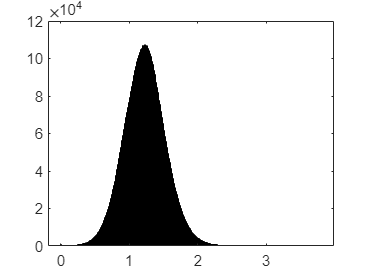

histogram(trainFeatures)

[Mdl, tf, scores] = iforest(trainFeatures,"CategoricalPredictors","all")

Mdl =   IsolationForest

        CategoricalPredictors: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 76 … ]
        ContaminationFraction: 0
               ScoreThreshold: 1
                  NumLearners: 100
    NumObservationsPerLearner: 256


  Properties, Methods


tf = 50000×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


scores = 50000×1 single column vector
    1.0000
    0.9939
    0.9966
    1.0000
    0.9933
    0.9846
    1.0000
    1.0000
    0.9939
    0.9933


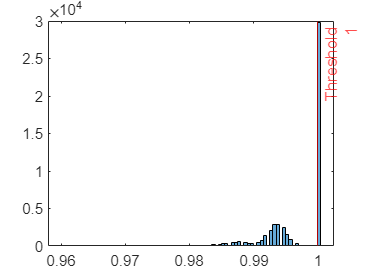

histogram(scores)
xline(Mdl.ScoreThreshold,"r-",["Threshold" Mdl.ScoreThreshold])

[tf_test,s_test] = isanomaly(Mdl, testFeatures)

tf_test = 1000×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


s_test = 1000×1 single column vector
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


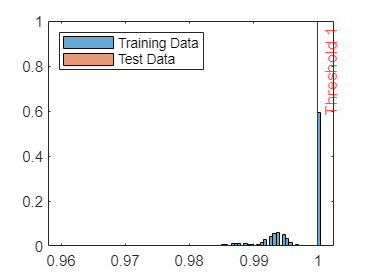

histogram(scores,Normalization="probability")
hold on
histogram(s_test,Normalization="probability")
xline(Mdl.ScoreThreshold,"r-",join(["Threshold" Mdl.ScoreThreshold]))
legend("Training Data","Test Data",Location="northwest")
hold off